%% PRÁCTICA 4 - Parte 1 (a)
% Análisis MPEG1 Audio Nivel I - Selección y características del archivo

clear; clc;

% --- Selección del fichero de audio (no voz) ---
audioFile = 'P4audioSTM.wav';   % Cambia el nombre si eliges otro .wav del ZIP

% --- Metadatos y lectura ---
if ~isfile(audioFile)
    error('No se encuentra %s en el directorio actual. Copia el WAV aquí o ajusta la ruta.', audioFile);
end

info = audioinfo(audioFile);     % Frecuencia, canales, duración, etc.
d    = dir(audioFile);           % Tamaño en bytes

% --- Impresión de resultados ---
fprintf('Archivo elegido: %s\n', audioFile);

Archivo elegido: P4audioSTM.wav


fprintf('Tipo: audio musical (no voz)\n');

Tipo: audio musical (no voz)


fprintf('Frecuencia de muestreo: %d Hz\n', info.SampleRate);

Frecuencia de muestreo: 44100 Hz


fprintf('Canales: %d\n', info.NumChannels);

Canales: 2


fprintf('Duración: %.2f s\n', info.Duration);

Duración: 19.97 s


fprintf('Tamaño: %d bytes (%.2f MB)\n', d.bytes, d.bytes/2^20);

Tamaño: 5282874 bytes (5.04 MB)



% --- Carga de señal para etapas posteriores ---
[x, Fs] = audioread(audioFile);  %#ok<NASGU>
% x: señal (NxC), Fs: frecuencia de muestreo

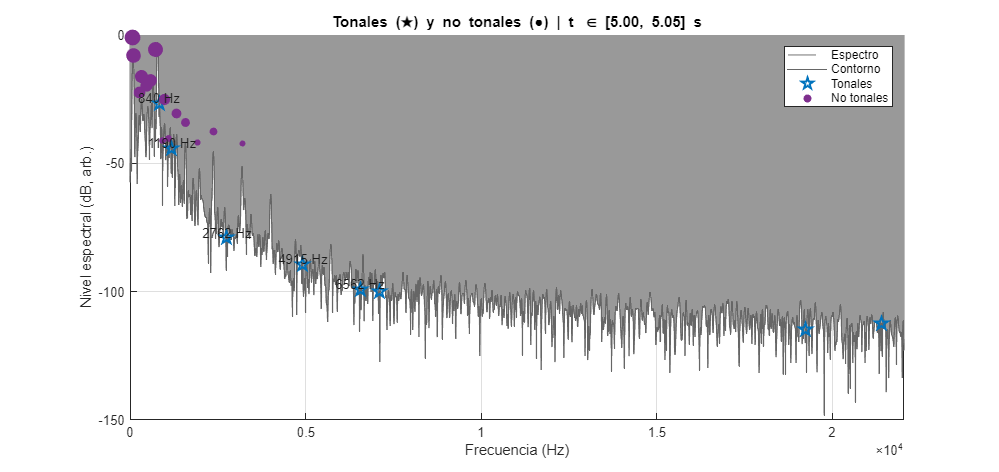

%% PRÁCTICA 4 - Parte 1 (b)
% MPEG-1 Audio Layer I: componentes TONALES y NO TONALES
% Versión robusta + detección adaptativa + fallback + leyendas dinámicas
% Autor: Andrés

clear; clc; close all;

%% --- Archivo y lectura ---
audioFile = 'P4audioSTM.wav';     % <-- cambia si eliges otro WAV
if ~isfile(audioFile), error('No se encuentra %s.', audioFile); end
[x, Fs] = audioread(audioFile);

% Mono para análisis psicoacústico
if size(x,2) > 1, x = mean(x,2); end
x = x(:);  N = length(x);

%% --- Fragmento pequeño (padding) ---
t0_sec = 5.0;      % inicio (s)
Nframe = 2048;     % tamaño de trama
Nfft   = 8192;     % zero-padding

n0   = max(1, round(t0_sec*Fs));
nEnd = min(N, n0 + Nframe - 1);

xw = zeros(Nframe,1);
xseg = x(n0:nEnd);
xw(1:numel(xseg)) = xseg;

w = hann(Nframe, 'periodic');
xw = xw .* w;

%% --- FFT y espectro ---
X      = fft(xw, Nfft);
binHz  = Fs/Nfft;
f      = (0:Nfft-1)*binHz;
Xpos   = X(1:floor(Nfft/2)+1);
fpos   = f(1:floor(Nfft/2)+1);

Ew     = sum(w.^2);
Mag2   = (abs(Xpos).^2) / max(Ew, eps);     % potencia normalizada
Pxx_dB = 10*log10(Mag2 + eps);

%% --- Auxiliares Bark / Índices ---
bark   = @(hz) 13*atan(0.00076*hz) + 3.5*atan((hz/7500).^2);
bin2hz = @(ii) fpos(ii);
hz2bin = @(hz) max(1, min(numel(fpos), round(hz/binHz) + 1));

%% --- Suavizado ligero para prominencia (evita picos espurios) ---
% (no se usa para dibujar, solo para calcular prominencias robustas)
winS  = 9; winS = winS + mod(winS+1,2);        % impar
Psm   = movmedian(Pxx_dB, winS);
Prom  = Pxx_dB - Psm;                           % "prominencia local"

%% --- Detección adaptativa de picos candidatos ---
% Umbral de prominencia: se adapta al rango dinámico del fragmento
dynRange = max(Pxx_dB) - median(Pxx_dB);
minProm_dB = max(3, min(10, 0.25*dynRange));    % entre 3 y 10 dB aprox.

minPeakDist_Hz = 60;                            % separación mínima
minPeakDist    = max(1, round(minPeakDist_Hz/binHz));

[pkVal0, pkIdx0] = findpeaks(Pxx_dB, ...
    'MinPeakProminence', minProm_dB, ...
    'MinPeakDistance',   minPeakDist);

% Filtra frecuencias demasiado bajas/altas (evitar DC/Nyquist)
valid = fpos(pkIdx0) > 50 & fpos(pkIdx0) < (Fs/2 - 1);
pkIdx0 = pkIdx0(valid); 
pkVal0 = pkVal0(valid);

%% --- Chequeo de vecindad (±1..±3 bins) con umbral adaptativo ---
% Si hay pocos picos, relajamos a +3 dB; si hay bastantes, +5 dB.
if numel(pkIdx0) < 6
    neighGain = 3;
else
    neighGain = 5;
end

keep = true(size(pkIdx0));
for k = 1:numel(pkIdx0)
    i = pkIdx0(k);
    neigh = [];
    for d = 1:3
        if i-d >= 1,               neigh(end+1) = Pxx_dB(i-d); end %#ok<AGROW>
        if i+d <= numel(Pxx_dB),   neigh(end+1) = Pxx_dB(i+d); end %#ok<AGROW>
    end
    if ~isempty(neigh) && pkVal0(k) < mean(neigh) + neighGain
        keep(k) = false;
    end
end
pkIdx = pkIdx0(keep);
pkVal = pkVal0(keep);

%% --- Fallback: si no quedó ningún tonal, fuerza los K picos más prominentes ---
if isempty(pkIdx)
    K = 8;  % número de picos a mostrar si no pasa nadie el filtro
    % Usa la prominencia "Prom" calculada con movmedian
    [~, ordAll] = sort(Prom, 'descend');
    % Evita DC/Nyquist y muy baja frecuencia
    ordAll = ordAll(fpos(ordAll) > 50 & fpos(ordAll) < (Fs/2 - 1));
    pkIdx = ordAll(1:min(K, numel(ordAll)));
    pkVal = Pxx_dB(pkIdx);
end

%% --- Zona tonal (±0.5 Bark) para aislar no-tonales ---
maskBins = false(size(Pxx_dB));
for k = 1:numel(pkIdx)
    fc  = bin2hz(pkIdx(k));
    zc  = bark(fc);
    zLo = max(0, zc - 0.5);
    zHi = zc + 0.5;

    % Inversión Bark->Hz robusta
    barkErr = @(h,z) bark(h) - z;
    hzFromZ = @(z) fminbnd(@(h) abs(barkErr(h,z)), max(0,fc-2000), min(Fs/2,fc+2000));
    try
        fLo = max(0, hzFromZ(zLo));
        fHi = min(Fs/2, hzFromZ(zHi));
        if ~isfinite(fLo) || ~isfinite(fHi), error('invBark'); end
    catch
        fLo = max(0, fc - 200);
        fHi = min(Fs/2, fc + 200);
    end

    iLo = hz2bin(fLo);  iHi = hz2bin(fHi);
    if iHi >= iLo, maskBins(iLo:iHi) = true; end
end

%% --- Residual espectral (NO TONAL) ---
residualPow = Mag2;
residualPow(maskBins) = 0;
residual_dB = 10*log10(residualPow + eps);

%% --- Agregado NO TONAL por bandas críticas ---
cbEdges = [0 100 200 300 400 510 630 770 920 1080 1270 1480 1720 2000 ...
           2320 2700 3150 3700 4400 5300 6400 7700 9500 12000 15500];
cbEdges(cbEdges > Fs/2) = Fs/2; 
cbEdges = unique(cbEdges);
Nc = numel(cbEdges)-1;

nonTonalFreq   = []; 
nonTonalLev_dB = []; 
nonTonalBand   = [];

for c = 1:Nc
    iLo = hz2bin(cbEdges(c));
    iHi = hz2bin(cbEdges(c+1));
    if iHi <= iLo, continue; end

    bandPow = residualPow(iLo:iHi);  bandPow = bandPow(:);
    bandF   = fpos(iLo:iHi);         bandF   = bandF(:);

    bad = ~isfinite(bandPow) | ~isfinite(bandF);
    if any(bad), bandPow(bad) = []; bandF(bad) = []; end
    if isempty(bandPow), continue; end

    E = sum(bandPow);
    if E > 0
        fBar = sum(bandPow .* bandF) / E;
        LdB  = 10*log10(E + eps);
        nonTonalFreq(end+1)   = fBar;     %#ok<SAGROW>
        nonTonalLev_dB(end+1) = LdB;      %#ok<SAGROW>
        nonTonalBand(end+1)   = c;        %#ok<SAGROW>
    end
end

% Filtrado visual de no-tonales muy débiles
if ~isempty(nonTonalLev_dB)
    thrNT = max(Pxx_dB) - 40;
    keepNT = nonTonalLev_dB > thrNT;
    nonTonalFreq   = nonTonalFreq(keepNT);
    nonTonalLev_dB = nonTonalLev_dB(keepNT);
    nonTonalBand   = nonTonalBand(keepNT);
end

%% --- Visualización 1: Espectro “lollipop” con TONALES y NO TONALES ---
figure('Color','w','Position',[100 100 1100 520]);
hold on; grid on; box on;

hLeg = gobjects(0); names = {};

% Espectro base
h1 = stem(fpos, Pxx_dB, 'Marker','none','LineWidth',1,'Color',[0.6 0.6 0.6], ...
          'DisplayName','Espectro'); 
hLeg(end+1) = h1; names{end+1} = get(h1,'DisplayName');

% Contorno
h2 = plot(fpos, Pxx_dB, 'LineWidth',0.5, 'Color',[0.4 0.4 0.4], ...
          'DisplayName','Contorno');
hLeg(end+1) = h2; names{end+1} = get(h2,'DisplayName');

% TONALES (siempre existen por fallback)
h3 = plot(fpos(pkIdx), Pxx_dB(pkIdx), 'p', 'MarkerSize',10, 'LineWidth',1.5, ...
          'Color',[0 0.45 0.74], 'DisplayName','Tonales');
hLeg(end+1) = h3; names{end+1} = get(h3,'DisplayName');

% NO TONALES (si hay)
if ~isempty(nonTonalFreq)
    sz = rescale(nonTonalLev_dB, 20, 140);
    h4 = scatter(nonTonalFreq, nonTonalLev_dB, sz, 'filled', 'DisplayName','No tonales');
    hLeg(end+1) = h4; names{end+1} = get(h4,'DisplayName');
end

xlabel('Frecuencia (Hz)'); ylabel('Nivel espectral (dB, arb.)');
title(sprintf('Tonales (★) y no tonales (●) | t \\in [%.2f, %.2f] s', ...
      (n0-1)/Fs, (n0+Nframe-1)/Fs));
xlim([0 Fs/2]);

legend(hLeg, names, 'Location','northeast');

% Etiquetas de las 5 tonales más fuertes
[~, ordPlot] = sort(Pxx_dB(pkIdx), 'descend');
for k = 1:min(5, numel(ordPlot))
    ii = pkIdx(ordPlot(k));
    text(fpos(ii), Pxx_dB(ii)+2, sprintf('%.0f Hz', fpos(ii)), ...
        'HorizontalAlignment','center','Color',[0.1 0.1 0.1]);
end

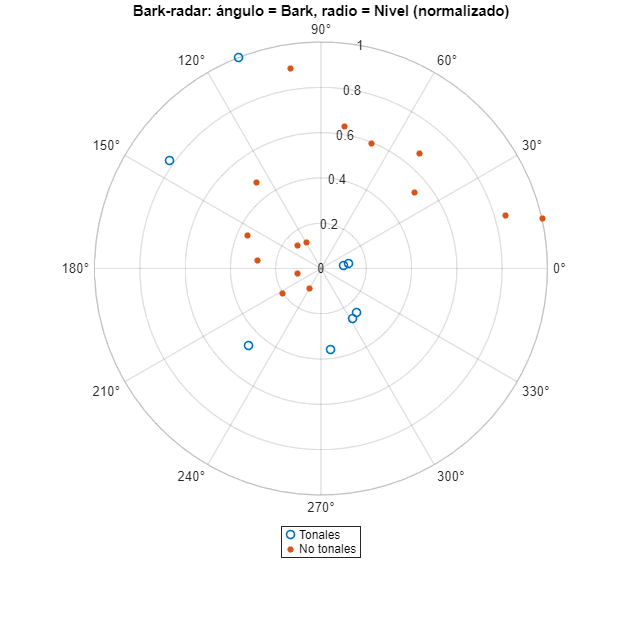


%% --- Visualización 2: “Bark-radar” (polar) creativo ---
figure('Color','w','Position',[150 150 620 620]);
ax = polaraxes; hold(ax,'on');

hLeg2 = gobjects(0); names2 = {};

% Tonales (siempre hay por fallback)
zTon = bark(fpos(pkIdx));
rTon = rescale(Pxx_dB(pkIdx), 0.1, 1.0);
hT = polarplot(ax, zTon/24*2*pi, rTon, 'o', 'LineWidth',1.2, 'MarkerSize',6, ...
               'DisplayName','Tonales');
hLeg2(end+1) = hT; names2{end+1} = get(hT,'DisplayName');

% No tonales
if ~isempty(nonTonalFreq)
    zNT  = bark(nonTonalFreq);
    rNT  = rescale(nonTonalLev_dB, 0.1, 1.0);
    hN = polarplot(ax, zNT/24*2*pi, rNT, '.', 'MarkerSize',14, ...
                   'DisplayName','No tonales');
    hLeg2(end+1) = hN; names2{end+1} = get(hN,'DisplayName');
end

title('Bark-radar: ángulo = Bark, radio = Nivel (normalizado)');
legend(hLeg2, names2, 'Location','southoutside');


%% --- Resumen en consola ---
fprintf('\n--- Resumen (b) ---\n');


--- Resumen (b) ---


fprintf('Fragmento: t = [%.2f, %.2f] s  |  Nframe=%d, Nfft=%d\n', ...
    (n0-1)/Fs, (n0+Nframe-1)/Fs, Nframe, Nfft);

Fragmento: t = [5.00, 5.05] s  |  Nframe=2048, Nfft=8192


fprintf('TONALES: %d\n', numel(pkIdx));

TONALES: 8


for k = 1:numel(pkIdx)
    fprintf('  #%02d  f=%.1f Hz   L=%.1f dB\n', k, fpos(pkIdx(k)), Pxx_dB(pkIdx(k)));
end

  #01  f=7100.6 Hz   L=-100.0 dB
  #02  f=1189.7 Hz   L=-44.0 dB
  #03  f=839.8 Hz   L=-26.6 dB
  #04  f=6562.2 Hz   L=-99.0 dB
  #05  f=21414.8 Hz   L=-112.4 dB
  #06  f=2761.6 Hz   L=-79.0 dB
  #07  f=19256.1 Hz   L=-114.6 dB
  #08  f=4915.0 Hz   L=-89.3 dB


fprintf('NO TONALES (bandas): %d\n', numel(nonTonalFreq));

NO TONALES (bandas): 15


for k = 1:numel(nonTonalFreq)
    fprintf('  #%02d  f_rep=%.1f Hz   L_band=%.1f dB   (CB=%d)\n', ...
        k, nonTonalFreq(k), nonTonalLev_dB(k), nonTonalBand(k));
end

  #01  f_rep=85.3 Hz   L_band=-0.8 dB   (CB=1)
  #02  f_rep=108.4 Hz   L_band=-7.8 dB   (CB=2)
  #03  f_rep=266.9 Hz   L_band=-22.6 dB   (CB=3)
  #04  f_rep=341.1 Hz   L_band=-16.1 dB   (CB=4)
  #05  f_rep=476.1 Hz   L_band=-19.5 dB   (CB=5)
  #06  f_rep=576.0 Hz   L_band=-17.6 dB   (CB=6)
  #07  f_rep=725.1 Hz   L_band=-5.8 dB   (CB=7)
  #08  f_rep=916.3 Hz   L_band=-41.0 dB   (CB=8)
  #09  f_rep=991.0 Hz   L_band=-25.0 dB   (CB=9)
  #10  f_rep=1091.9 Hz   L_band=-40.3 dB   (CB=10)
  #11  f_rep=1331.6 Hz   L_band=-30.7 dB   (CB=11)
  #12  f_rep=1578.1 Hz   L_band=-33.9 dB   (CB=12)
  #13  f_rep=1914.5 Hz   L_band=-42.0 dB   (CB=13)
  #14  f_rep=2373.7 Hz   L_band=-37.6 dB   (CB=15)
  #15  f_rep=3203.5 Hz   L_band=-42.4 dB   (CB=17)


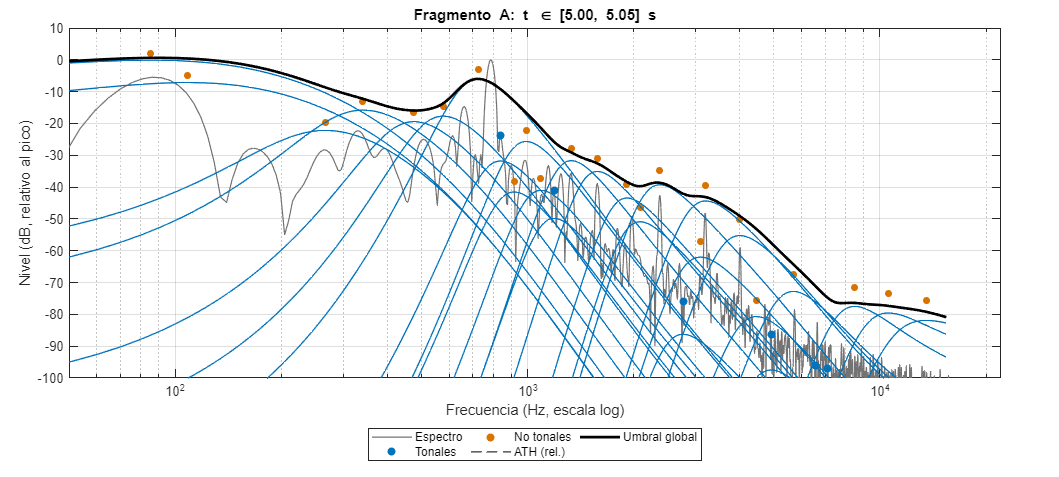

%% PRÁCTICA 4 - Parte 1 (c)
% Enmascaramiento y umbrales (dos fragmentos) – versión normalizada y robusta
% Autor: Andrés

clear; clc; close all;

%% ------------------ Configuración ------------------
audioFile = 'P4audioSTM.wav';              % <-- cambia si usas otro WAV
if ~isfile(audioFile), error('No se encuentra %s.', audioFile); end
[x, Fs] = audioread(audioFile);
if size(x,2) > 1, x = mean(x,2); end
x = x(:);

% Fragmentos a analizar (s)
t0_a = 5.00;    % fragmento A
t0_b = 12.50;   % fragmento B

% Parámetros de análisis
Nframe = 2048;        % tamaño de trama
Nfft   = 8192;        % zero-padding

% Grid Bark para evaluar umbrales
zGrid = linspace(0,24,241);  % 0:0.1:24

% Helpers de FFT
binHz  = Fs/Nfft;
freqs  = (0:Nfft-1)*binHz;
fposIx = 1:floor(Nfft/2)+1;
fpos   = freqs(fposIx);

% Función Bark (Zwicker)
bark = @(hz) 13*atan(0.00076*hz) + 3.5*atan((hz/7500).^2);

%% ------------------ Proceso: fragmento A y B ------------------
Sa = analyze_fragment(x, Fs, t0_a, Nframe, Nfft, fpos, binHz, bark);
Ta = masking_thresholds(Sa, zGrid, bark, Fs);

Sb = analyze_fragment(x, Fs, t0_b, Nframe, Nfft, fpos, binHz, bark);
Tb = masking_thresholds(Sb, zGrid, bark, Fs);

%% ------------------ Visualización: Fragmento A ------------------
figure('Color','w','Position',[120 80 1200 540]); 
tiledlayout(1,1,'Padding','compact','TileSpacing','compact');
nexttile; hold on; grid on; box on;

hLeg = gobjects(0); names = {};

% Espectro normalizado (pico a 0 dB)
h1 = plot(Sa.fpos, Sa.Pxx_dB_norm, 'Color',[0.45 0.45 0.45], 'LineWidth',0.9, 'DisplayName','Espectro');
hLeg(end+1)=h1; names{end+1}=get(h1,'DisplayName');

% Tonales
if ~isempty(Sa.tonalF)
    h2 = scatter(Sa.tonalF, Sa.tonalL_norm, 36, 'filled', 'MarkerFaceColor',[0 0.45 0.74], ...
        'DisplayName','Tonales');
    hLeg(end+1)=h2; names{end+1}=get(h2,'DisplayName');
end

% No tonales
if ~isempty(Sa.nonF)
    h3 = scatter(Sa.nonF, Sa.nonL_norm, 28, 'filled', 'MarkerFaceColor',[0.85 0.45 0], ...
        'DisplayName','No tonales');
    hLeg(end+1)=h3; names{end+1}=get(h3,'DisplayName');
end

% Curvas individuales (líneas finas)
if ~isempty(Ta.T_ind)
    for m = 1:size(Ta.T_ind,2)
        plot(Ta.fGrid, Ta.T_ind(:,m), 'Color',[0 0.45 0.74], 'LineWidth',0.6);
    end
end

% ATH relativo y Umbral Global
h4 = plot(Ta.fGrid, Ta.T_ATH, '--', 'Color',[0.2 0.2 0.2], 'LineWidth',1.0, 'DisplayName','ATH (rel.)');
hLeg(end+1)=h4; names{end+1}=get(h4,'DisplayName');

h5 = plot(Ta.fGrid, Ta.Tg, 'k', 'LineWidth',2.0, 'DisplayName','Umbral global');
hLeg(end+1)=h5; names{end+1}=get(h5,'DisplayName');

set(gca,'XScale','log');
xlim([50 Fs/2]); ylim([-100 10]);
xlabel('Frecuencia (Hz, escala log)'); ylabel('Nivel (dB, relativo al pico)');
title(sprintf('Fragmento A: t \\in [%.2f, %.2f] s', t0_a, t0_a + (Nframe-1)/Fs));
legend(hLeg, names, 'Location','southoutside','NumColumns',3);

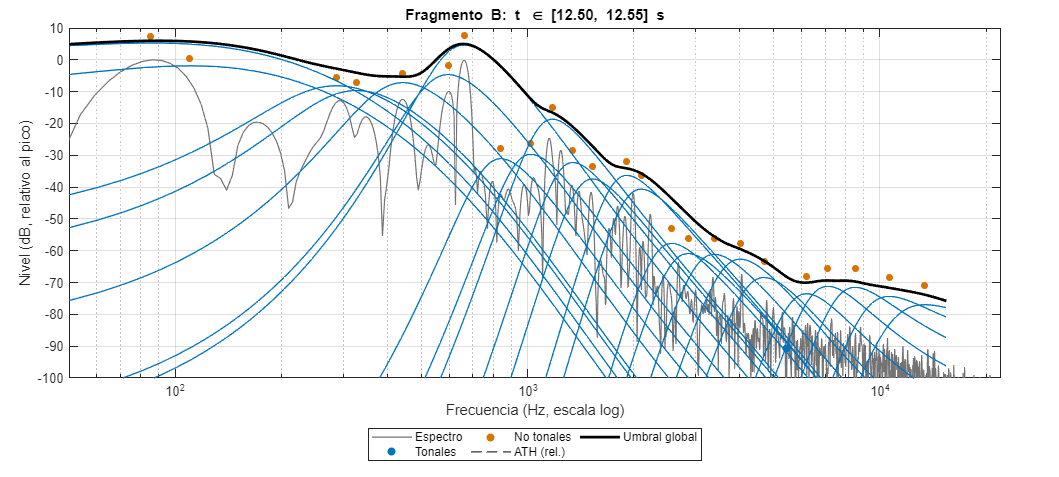


%% ------------------ Visualización: Fragmento B ------------------
figure('Color','w','Position',[120 670 1200 540]); 
tiledlayout(1,1,'Padding','compact','TileSpacing','compact');
nexttile; hold on; grid on; box on;

hLeg = gobjects(0); names = {};

% Espectro normalizado
h1 = plot(Sb.fpos, Sb.Pxx_dB_norm, 'Color',[0.45 0.45 0.45], 'LineWidth',0.9, 'DisplayName','Espectro');
hLeg(end+1)=h1; names{end+1}=get(h1,'DisplayName');

% Tonales
if ~isempty(Sb.tonalF)
    h2 = scatter(Sb.tonalF, Sb.tonalL_norm, 36, 'filled', 'MarkerFaceColor',[0 0.45 0.74], ...
        'DisplayName','Tonales');
    hLeg(end+1)=h2; names{end+1}=get(h2,'DisplayName');
end

% No tonales
if ~isempty(Sb.nonF)
    h3 = scatter(Sb.nonF, Sb.nonL_norm, 28, 'filled', 'MarkerFaceColor',[0.85 0.45 0], ...
        'DisplayName','No tonales');
    hLeg(end+1)=h3; names{end+1}=get(h3,'DisplayName');
end

% Curvas individuales
if ~isempty(Tb.T_ind)
    for m = 1:size(Tb.T_ind,2)
        plot(Tb.fGrid, Tb.T_ind(:,m), 'Color',[0 0.45 0.74], 'LineWidth',0.6);
    end
end

% ATH y Umbral Global
h4 = plot(Tb.fGrid, Tb.T_ATH, '--', 'Color',[0.2 0.2 0.2], 'LineWidth',1.0, 'DisplayName','ATH (rel.)');
hLeg(end+1)=h4; names{end+1}=get(h4,'DisplayName');

h5 = plot(Tb.fGrid, Tb.Tg, 'k', 'LineWidth',2.0, 'DisplayName','Umbral global');
hLeg(end+1)=h5; names{end+1}=get(h5,'DisplayName');

set(gca,'XScale','log');
xlim([50 Fs/2]); ylim([-100 10]);
xlabel('Frecuencia (Hz, escala log)'); ylabel('Nivel (dB, relativo al pico)');
title(sprintf('Fragmento B: t \\in [%.2f, %.2f] s', t0_b, t0_b + (Nframe-1)/Fs));
legend(hLeg, names, 'Location','southoutside','NumColumns',3);

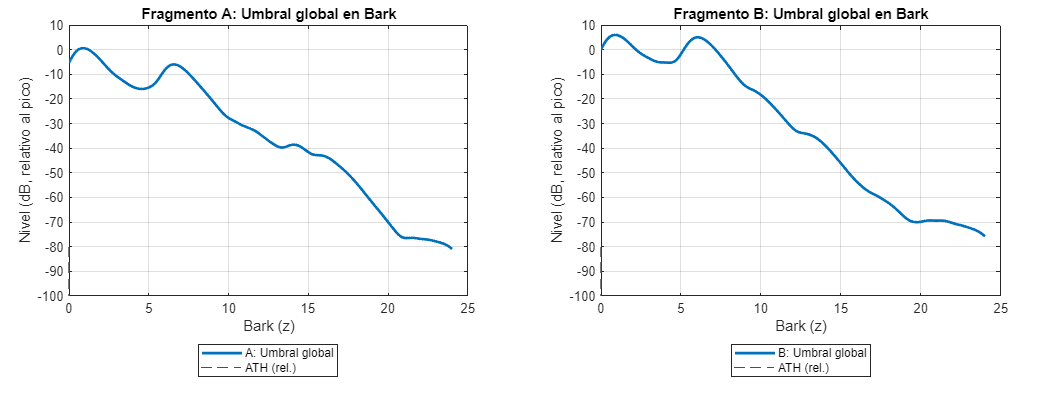

%% ------------------ Comparativa Bark (A vs B) ------------------
figure('Color','w','Position',[200 80 1400 520]);  % figura más ancha
tl = tiledlayout(1,2,'TileSpacing','loose','Padding','compact');

% --- Fragmento A ---
nexttile; hold on; grid on; box on;
plot(Ta.z, Ta.Tg, 'LineWidth',2.0, 'DisplayName','A: Umbral global');
plot(Ta.z, Ta.T_ATH, '--', 'Color',[0.3 0.3 0.3], 'DisplayName','ATH (rel.)');
xlabel('Bark (z)'); ylabel('Nivel (dB, relativo al pico)'); ylim([-100 10]);
title('Fragmento A: Umbral global en Bark'); legend('Location','southoutside');

% --- Fragmento B ---
nexttile; hold on; grid on; box on;
plot(Tb.z, Tb.Tg, 'LineWidth',2.0, 'DisplayName','B: Umbral global');
plot(Tb.z, Tb.T_ATH, '--', 'Color',[0.3 0.3 0.3], 'DisplayName','ATH (rel.)');
xlabel('Bark (z)'); ylabel('Nivel (dB, relativo al pico)'); ylim([-100 10]);
title('Fragmento B: Umbral global en Bark'); legend('Location','southoutside');


%% ------------------ Resumen en consola ------------------
fprintf('\n--- Parte 1 (c) [normalizada] ---\n');


--- Parte 1 (c) [normalizada] ---


fprintf('Frag A: t=[%.2f, %.2f]s | Tonales=%d, NoTonales=%d | Pico espectral=0 dB\n', ...
    t0_a, t0_a + (Nframe-1)/Fs, numel(Sa.tonalF), numel(Sa.nonF));

Frag A: t=[5.00, 5.05]s | Tonales=8, NoTonales=23 | Pico espectral=0 dB


fprintf('Frag B: t=[%.2f, %.2f]s | Tonales=%d, NoTonales=%d | Pico espectral=0 dB\n', ...
    t0_b, t0_b + (Nframe-1)/Fs, numel(Sb.tonalF), numel(Sb.nonF));

Frag B: t=[12.50, 12.55]s | Tonales=1, NoTonales=24 | Pico espectral=0 dB



%% ================== FUNCIONES LOCALES ==================
function S = analyze_fragment(x, Fs, t0, Nframe, Nfft, fpos, binHz, bark)
    N = numel(x);
    n0   = max(1, round(t0*Fs));
    nEnd = min(N, n0 + Nframe - 1);

    xw = zeros(Nframe,1); 
    xseg = x(n0:nEnd);
    xw(1:numel(xseg)) = xseg;

    w = hann(Nframe, 'periodic');
    xw = xw .* w;

    X      = fft(xw, Nfft);
    Ew     = sum(w.^2);
    Xpos   = X(1:floor(Nfft/2)+1);
    Mag2   = (abs(Xpos).^2) / max(Ew, eps);
    Pxx_dB = 10*log10(Mag2 + eps);

    % Normalización a 0 dB pico
    Pxx_dB_norm = Pxx_dB - max(Pxx_dB);

    % Suavizado para prominencia
    winS = 9; winS = winS + mod(winS+1,2);
    Psm  = movmedian(Pxx_dB_norm, winS);
    Prom = Pxx_dB_norm - Psm;

    % Detección adaptativa
    dynRange = max(Pxx_dB_norm) - median(Pxx_dB_norm);
    minProm_dB = max(3, min(10, 0.25*abs(dynRange)));
    minPeakDist_Hz = 60; minPeakDist = max(1, round(minPeakDist_Hz/binHz));

    [~, pkIdx0] = findpeaks(Pxx_dB_norm, ...
        'MinPeakProminence', minProm_dB, ...
        'MinPeakDistance',   minPeakDist);

    valid = fpos(pkIdx0) > 50 & fpos(pkIdx0) < (Fs/2 - 1);
    pkIdx0 = pkIdx0(valid); 

    % Chequeo vecindad (±1..±3 bins)
    neighGain = (numel(pkIdx0) < 6) * 3 + (numel(pkIdx0) >= 6) * 5;
    keep = true(size(pkIdx0));
    for k = 1:numel(pkIdx0)
        i = pkIdx0(k); neigh = [];
        for d = 1:3
            if i-d >= 1, neigh(end+1) = Pxx_dB_norm(i-d); end %#ok<AGROW>
            if i+d <= numel(Pxx_dB_norm), neigh(end+1) = Pxx_dB_norm(i+d); end %#ok<AGROW>
        end
        if ~isempty(neigh) && Pxx_dB_norm(i) < mean(neigh) + neighGain
            keep(k) = false;
        end
    end
    pkIdx = pkIdx0(keep);

    % Fallback si no queda ninguno
    if isempty(pkIdx)
        K = 8;
        [~, ord] = sort(Prom, 'descend');
        ord = ord(fpos(ord) > 50 & fpos(ord) < (Fs/2 - 1));
        pkIdx = ord(1:min(K, numel(ord)));
    end

    % Máscara tonal (±0.5 Bark) para separar no-tonales
    maskBins = false(size(Pxx_dB_norm));
    for k = 1:numel(pkIdx)
        fc  = fpos(pkIdx(k));
        zc  = bark(fc);
        zLo = max(0, zc - 0.5);
        zHi = zc + 0.5;

        try
            fLo = fminbnd(@(h) abs(bark(h)-zLo), 0, Fs/2);
            fHi = fminbnd(@(h) abs(bark(h)-zHi), 0, Fs/2);
        catch
            fLo = max(0, fc-200); fHi = min(Fs/2, fc+200);
        end
        iLo = max(1, min(numel(Pxx_dB_norm), round(fLo/binHz)+1));
        iHi = max(1, min(numel(Pxx_dB_norm), round(fHi/binHz)+1));
        if iHi >= iLo, maskBins(iLo:iHi) = true; end
    end

    residualPow = Mag2; residualPow(maskBins) = 0;

    % No-tonales agregados por bandas críticas aproximadas
    cbEdges = [0 100 200 300 400 510 630 770 920 1080 1270 1480 1720 2000 ...
               2320 2700 3150 3700 4400 5300 6400 7700 9500 12000 15500];
    cbEdges(cbEdges > Fs/2) = Fs/2; cbEdges = unique(cbEdges);
    Nc = numel(cbEdges)-1;

    nonF = []; nonL_norm = [];
    for c = 1:Nc
        iLo = max(1, round(cbEdges(c)/binHz)+1);
        iHi = max(1, round(cbEdges(c+1)/binHz)+1);
        iLo = min(iLo, numel(fpos)); iHi = min(iHi, numel(fpos));
        if iHi <= iLo, continue; end

        bandPow = residualPow(iLo:iHi); bandPow = bandPow(:);
        bandF   = fpos(iLo:iHi);        bandF   = bandF(:);
        bad = ~isfinite(bandPow) | ~isfinite(bandF);
        if any(bad), bandPow(bad)=[]; bandF(bad)=[]; end
        if isempty(bandPow), continue; end

        E = sum(bandPow);
        if E > 0
            fBar = sum(bandPow .* bandF) / E;
            LdB  = 10*log10(E + eps);
            nonF(end+1)      = fBar;           %#ok<SAGROW>
            nonL_norm(end+1) = LdB - max(Pxx_dB); %#ok<SAGROW>  % normalizado al mismo 0 dB
        end
    end

    % Salida (normalizada)
    S.t0          = t0;
    S.fpos        = fpos(:);
    S.Pxx_dB_norm = Pxx_dB_norm(:);

    tmp = fpos(pkIdx);      S.tonalF      = tmp(:);
    tmp = Pxx_dB_norm(pkIdx); S.tonalL_norm = tmp(:);

    S.nonF      = nonF(:);
    S.nonL_norm = nonL_norm(:);
end

function T = masking_thresholds(S, zGrid, bark, Fs)
    % Spreading function de Zwicker (dB)
    SF_dB  = @(dz) 15.81 + 7.5*(dz + 0.474) - 17.5*sqrt(1 + (dz + 0.474).^2);
    % ATH (Zwicker) y versión relativa
    ATH_abs = @(f) 3.64*((f/1000).^(-0.8)) - 6.5*exp(-0.6*(f/1000 - 3.3).^2) + 0.001*(f/1000).^4;

    z = zGrid(:);                    % Nzx1

    % Lista de maskers (normalizados)
    fMask = [S.tonalF; S.nonF];             fMask = fMask(:);
    LMask = [S.tonalL_norm; S.nonL_norm];   LMask = LMask(:);
    type  = [true(numel(S.tonalF),1); false(numel(S.nonF),1)];

    M = numel(fMask);

    % fGrid(z): inversa global Bark->Hz en [0, Fs/2]
    Nz = numel(z);
    fGrid = zeros(Nz,1);
    for k = 1:Nz
        try
            fGrid(k) = fminbnd(@(h) abs(bark(h)-z(k)), 0, Fs/2);
        catch
            % aproximación monotónica si fminbnd falla
            fGrid(k) = min(Fs/2, max(0, 650*(exp(z(k)/7)-1)));
        end
    end

    % ATH relativo: conserva forma pero lo situamos ~80 dB por debajo del 0 dB del fragmento
    ATHshape = ATH_abs(fGrid);                   % dB SPL-like
    T_ATH    = ATHshape - (max(ATHshape) + 80);  % ~[-80 .. -20] dB relativos

    if M==0
        T_ind = nan(Nz,1);
        Tg    = T_ATH;
    else
        zMask = bark(fMask(:));

        % Correcciones (pedagógicas, en dB relativos)
        tonalCorr    = -0.275*zMask - 6.0;
        nonTonalCorr = -0.175*zMask - 2.0;
        corr = nonTonalCorr; corr(type) = tonalCorr(type);
        LEff = LMask + corr;

        % Curvas individuales
        T_ind = nan(Nz, M);
        for m = 1:M
            dz = z - zMask(m);
            sf = SF_dB(dz);                 % Nzx1
            T_ind(:,m) = LEff(m) + sf(:);
        end

        % Umbral global por suma de potencias + ATH relativo
        powMask = 10.^(T_ind/10);                 % NzxM
        powSum  = nansum(powMask, 2);             % Nzx1
        powSum  = powSum + 10.^(T_ATH/10);
        Tg      = 10*log10(powSum + eps);
    end

    % Salidas
    T.z     = z;          % Nzx1
    T.fGrid = fGrid;      % Nzx1
    T.T_ind = T_ind;      % NzxM (o Nzx1 NaN si M=0)
    T.T_ATH = T_ATH;      % Nzx1 (relativo)
    T.Tg    = Tg;         % Nzx1 (relativo)
end

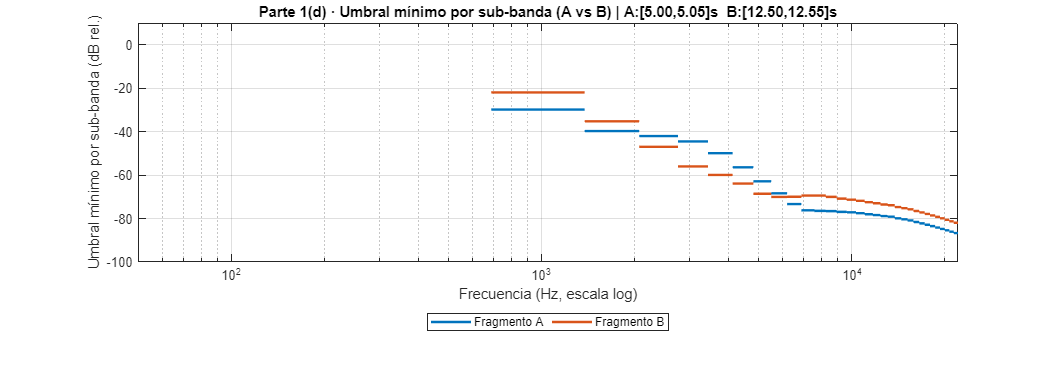

%% PRÁCTICA 4 - Parte 1 (d)
% Umbral de enmascaramiento MÍNIMO por SUB-BANDA (MPEG-1 Layer I, 32 bandas)
% para dos fragmentos del audio. Versión robusta y normalizada. (Leyenda FIX)
% Autor: Andrés

clear; clc; close all;

%% ------------------ Configuración ------------------
audioFile = 'P4audioSTM.wav';           % <-- cambia si usas otro WAV
if ~isfile(audioFile), error('No se encuentra %s.', audioFile); end
[x, Fs] = audioread(audioFile);
if size(x,2) > 1, x = mean(x,2); end
x = x(:);

% Fragmentos a analizar (s)
t0_a = 5.00;         % fragmento A
t0_b = 12.50;        % fragmento B

% Parámetros de análisis
Nframe = 2048;       % tamaño de trama
Nfft   = 8192;       % zero-padding

% Grid Bark
zGrid = linspace(0,24,241);   % 0:0.1:24

% Helpers FFT
binHz  = Fs/Nfft;
freqs  = (0:Nfft-1)*binHz;
fposIx = 1:floor(Nfft/2)+1;
fpos   = freqs(fposIx);

% Bark (Zwicker)
bark = @(hz) 13*atan(0.00076*hz) + 3.5*atan((hz/7500).^2);

% Definición de subbandas MPEG Layer I: 32 bandas uniformes en [0, Fs/2]
NB = 32;
sbEdges  = linspace(0, Fs/2, NB+1);
sbCenter = 0.5*(sbEdges(1:end-1) + sbEdges(2:end));

%% ------------------ (1) Analizar los dos fragmentos (reusa lógica de la parte c) ------------------
Sa = analyze_fragment(x, Fs, t0_a, Nframe, Nfft, fpos, binHz, bark);
Ta = masking_thresholds(Sa, zGrid, bark, Fs);  % Tg(f) relativo (dB)

Sb = analyze_fragment(x, Fs, t0_b, Nframe, Nfft, fpos, binHz, bark);
Tb = masking_thresholds(Sb, zGrid, bark, Fs);

%% ------------------ (2) Umbral mínimo por sub-banda ------------------
[TminA, TminB] = deal(nan(1, NB));

for b = 1:NB
    flo = sbEdges(b); fhi = sbEdges(b+1);
    % A
    idxA = Ta.fGrid >= flo & Ta.fGrid < fhi;
    if any(idxA)
        TminA(b) = min(Ta.Tg(idxA));
    else
        TminA(b) = interp1(Ta.fGrid, Ta.Tg, sbCenter(b), 'linear', 'extrap');
    end
    % B
    idxB = Tb.fGrid >= flo & Tb.fGrid < fhi;
    if any(idxB)
        TminB(b) = min(Tb.Tg(idxB));
    else
        TminB(b) = interp1(Tb.fGrid, Tb.Tg, sbCenter(b), 'linear', 'extrap');
    end
end

%% ------------------ (3) Gráficas ------------------

% 3.1 “Stairs” por frecuencia con leyenda correcta (usando NaN-separators)
figure('Color','w','Position',[100 80 1200 420]); hold on; grid on; box on;

% Construir una única serie por fragmento:
xA = reshape([sbEdges(1:end-1); sbEdges(2:end); nan(1,NB)], 1, []);
yA = reshape([TminA; TminA; nan(1,NB)], 1, []);
xB = reshape([sbEdges(1:end-1); sbEdges(2:end); nan(1,NB)], 1, []);
yB = reshape([TminB; TminB; nan(1,NB)], 1, []);

hA = plot(xA, yA, 'LineWidth', 1.8, 'Color', [0 0.45 0.74], 'DisplayName', 'Fragmento A');
hB = plot(xB, yB, 'LineWidth', 1.8, 'Color', [0.85 0.33 0.10], 'DisplayName', 'Fragmento B');

set(gca,'XScale','log');
xlim([max(50,sbEdges(1)+eps) Fs/2]); ylim([-100 10]);
xlabel('Frecuencia (Hz, escala log)'); ylabel('Umbral mínimo por sub-banda (dB rel.)');
title(sprintf('Parte 1(d) · Umbral mínimo por sub-banda (A vs B) | A:[%.2f,%.2f]s  B:[%.2f,%.2f]s', ...
      t0_a, t0_a+(Nframe-1)/Fs, t0_b, t0_b+(Nframe-1)/Fs));
legend([hA hB], {'Fragmento A','Fragmento B'}, 'Location','southoutside','NumColumns',2);

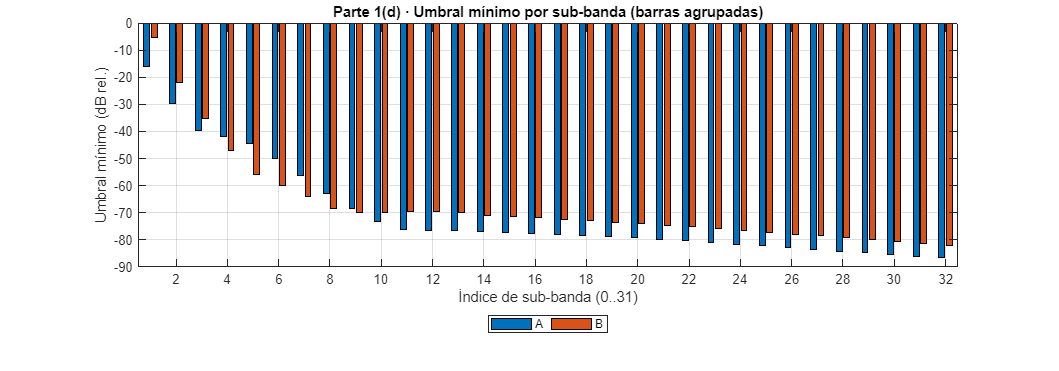


% 3.2 Barras agrupadas por índice de subbanda
figure('Color','w','Position',[100 520 1200 420]); 
bar(1:NB, [TminA(:) TminB(:)], 'grouped'); grid on; box on;
xlabel('Índice de sub-banda (0..31)'); ylabel('Umbral mínimo (dB rel.)');
title('Parte 1(d) · Umbral mínimo por sub-banda (barras agrupadas)');
legend({'A','B'}, 'Location','southoutside','NumColumns',2);
xticks(0:2:32); xticklabels(string(0:2:32));

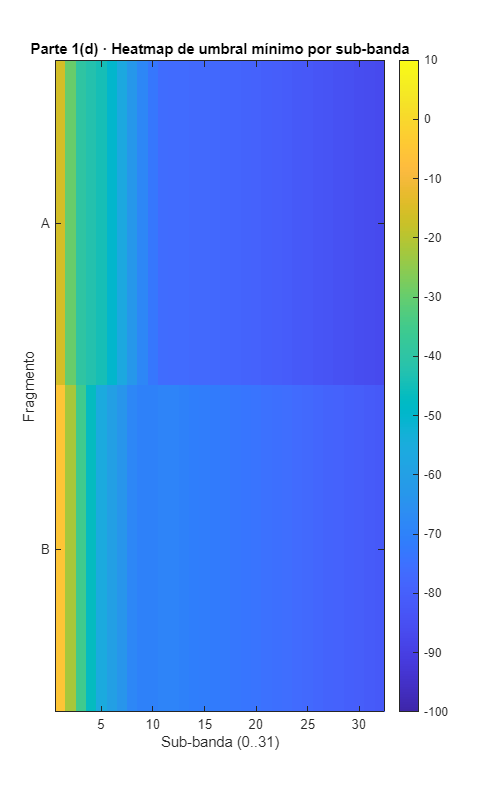


% 3.3 Heatmap comparativo (filas: A/B ; columnas: subbandas)
figure('Color','w','Position',[1340 80 520 860]);
imagesc(1:NB, 1:2, [TminA; TminB]); colorbar; caxis([-100 10]);
yticks([1 2]); yticklabels({'A','B'}); 
xlabel('Sub-banda (0..31)'); ylabel('Fragmento');
title('Parte 1(d) · Heatmap de umbral mínimo por sub-banda');


%% ------------------ (4) Resumen en consola ------------------
fprintf('\n--- Parte 1 (d) ---\n');


--- Parte 1 (d) ---


fprintf('Subbandas MPEG Layer I: %d bandas uniformes en [0, Fs/2]=[0, %.1f] Hz\n', NB, Fs/2);

Subbandas MPEG Layer I: 32 bandas uniformes en [0, Fs/2]=[0, 22050.0] Hz


fprintf('   Fragmento A t=[%.2f, %.2f] s\n', t0_a, t0_a+(Nframe-1)/Fs);

   Fragmento A t=[5.00, 5.05] s


fprintf('   Fragmento B t=[%.2f, %.2f] s\n', t0_b, t0_b+(Nframe-1)/Fs);

   Fragmento B t=[12.50, 12.55] s


fprintf('   Media Tmin A = %.1f dB | min=%.1f dB | max=%.1f dB\n', mean(TminA,'omitnan'), min(TminA), max(TminA));

   Media Tmin A = -70.5 dB | min=-86.7 dB | max=-15.9 dB


fprintf('   Media Tmin B = %.1f dB | min=%.1f dB | max=%.1f dB\n', mean(TminB,'omitnan'), min(TminB), max(TminB));

   Media Tmin B = -67.3 dB | min=-81.9 dB | max=-5.3 dB


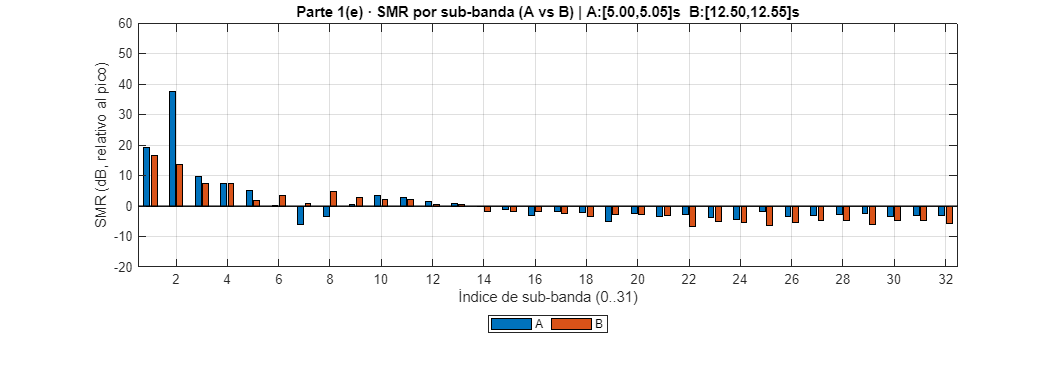

%% PRÁCTICA 4 - Parte 1 (e) · SMR por sub-banda (versión final coherente con (c)-(d))
clear; clc; close all;

% ---------------- Config ----------------
audioFile = 'P4audioSTM.wav';                 % cámbialo si usas otro
assert(isfile(audioFile), 'No se encuentra %s', audioFile);
[x, Fs] = audioread(audioFile);
if size(x,2)>1, x = mean(x,2); end
x = x(:);

% Fragmentos (s)
t0A = 5.00; t0B = 12.50;

% FFT / enmascaramiento
Nframe = 2048; Nfft = 8192;
binHz  = Fs/Nfft;
fpos   = (0:floor(Nfft/2))*binHz; fpos = fpos(:);
bark = @(hz) 13*atan(0.00076*hz) + 3.5*atan((hz/7500).^2);
zGrid = linspace(0,24,241); zGrid = zGrid(:);

% Subbandas MPEG Layer I (uniformes en [0, Fs/2])
NB = 32;
sbEdges  = linspace(0, Fs/2, NB+1);
sbCenter = 0.5*(sbEdges(1:end-1)+sbEdges(2:end));

% ---------------- Fragmentos -> espectro + Tg (como en (c)) ----------------
SA = frag_spectrum(x, Fs, t0A, Nframe, Nfft, fpos, binHz);
TA = compute_Tg(SA, zGrid, bark, Fs);   % devuelve Tg(f) relativo y fGrid

SB = frag_spectrum(x, Fs, t0B, Nframe, Nfft, fpos, binHz);
TB = compute_Tg(SB, zGrid, bark, Fs);

% ---------------- Señal por sub-banda (dB rel.) ----------------
LA = band_signal_dB(SA.Mag2, fpos, sbEdges, SA.maxPxx_dB);
LB = band_signal_dB(SB.Mag2, fpos, sbEdges, SB.maxPxx_dB);

% ---------------- Umbral mínimo por sub-banda -------------------
TminA = band_Tmin(TA.fGrid, TA.Tg, sbEdges, sbCenter);
TminB = band_Tmin(TB.fGrid, TB.Tg, sbEdges, sbCenter);

% ------------------- SMR (dB) ----------------------------------
SMR_A = LA - TminA;
SMR_B = LB - TminB;

% Saneado por si algo se descuadra numéricamente:
if any(~isfinite([SMR_A,SMR_B]))
    warning('Se detectaron valores no finitos en SMR; sustituyendo por NaN.');
    SMR_A(~isfinite(SMR_A)) = NaN; SMR_B(~isfinite(SMR_B)) = NaN;
end

% ------------------- Gráficas ----------------------------------
yl = [-20 60];   % rango típico visual de SMR en dB

% Barras agrupadas
figure('Color','w','Position',[80 80 1200 420]);
bar(1:NB, [SMR_A(:) SMR_B(:)], 'grouped'); grid on; box on;
yline(0,'k-','LineWidth',1.1);
ylim(yl); ax=gca; ax.YAxis.Exponent=0;
xlabel('Índice de sub-banda (0..31)'); ylabel('SMR (dB, relativo al pico)');
title(sprintf('Parte 1(e) · SMR por sub-banda (A vs B) | A:[%.2f,%.2f]s  B:[%.2f,%.2f]s', ...
      t0A, t0A+(Nframe-1)/Fs, t0B, t0B+(Nframe-1)/Fs));
legend({'A','B'}, 'Location','southoutside','NumColumns',2);
xticks(0:2:32); xticklabels(string(0:2:32));

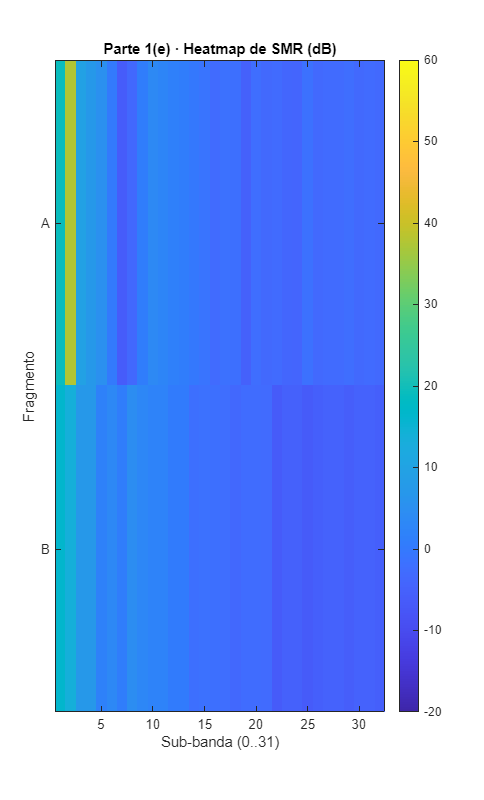


% Heatmap
figure('Color','w','Position',[1320 80 520 860]);
imagesc(1:NB, 1:2, [SMR_A; SMR_B]); colorbar; caxis(yl);
yticks([1 2]); yticklabels({'A','B'}); 
xlabel('Sub-banda (0..31)'); ylabel('Fragmento');
title('Parte 1(e) · Heatmap de SMR (dB)');

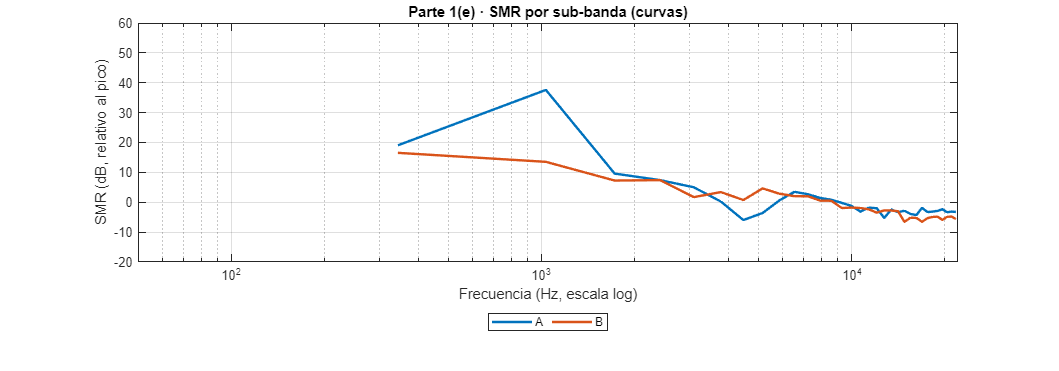


% Curvas vs frecuencia
figure('Color','w','Position',[80 520 1200 420]); hold on; grid on; box on;
plot(sbCenter, SMR_A, 'LineWidth',1.8, 'DisplayName','A');
plot(sbCenter, SMR_B, 'LineWidth',1.8, 'DisplayName','B');
set(gca,'XScale','log'); xlim([max(50,sbEdges(1)+eps) Fs/2]); ylim(yl); ax=gca; ax.YAxis.Exponent=0;
xlabel('Frecuencia (Hz, escala log)'); ylabel('SMR (dB, relativo al pico)');
title('Parte 1(e) · SMR por sub-banda (curvas)'); legend('Location','southoutside','NumColumns',2);


% Resumen en consola
fprintf('\n--- Parte 1 (e) · Resumen ---\n');


--- Parte 1 (e) · Resumen ---


fprintf('A: SMR medio=%.1f dB | mín=%.1f dB (sb %d)\n', mean(SMR_A,'omitnan'), min(SMR_A), find(SMR_A==min(SMR_A),1)-1);

A: SMR medio=0.8 dB | mín=-6.0 dB (sb 6)


fprintf('B: SMR medio=%.1f dB | mín=%.1f dB (sb %d)\n', mean(SMR_B,'omitnan'), min(SMR_B), find(SMR_B==min(SMR_B),1)-1);

B: SMR medio=-0.5 dB | mín=-6.6 dB (sb 21)



% ------------------- Funciones locales --------------------------
function S = frag_spectrum(x, Fs, t0, Nframe, Nfft, fpos, binHz)
    N = numel(x); n0 = max(1, round(t0*Fs)); nEnd = min(N, n0+Nframe-1);
    xw = zeros(Nframe,1); seg = x(n0:nEnd); xw(1:numel(seg)) = seg;
    w  = hann(Nframe,'periodic'); xw = xw .* w;
    X  = fft(xw, Nfft); Ew = sum(w.^2);
    Xp = X(1:floor(Nfft/2)+1);
    Mag2 = (abs(Xp).^2) / max(Ew, eps);
    Pxx_dB = 10*log10(Mag2 + eps);
    maxPxx = max(Pxx_dB);
    Pxx_dB_norm = Pxx_dB - maxPxx;

    % Detección básica (como en (c)) para maskers
    winS=9; winS=winS+mod(winS+1,2);
    Psm = movmedian(Pxx_dB_norm, winS);
    Prom= Pxx_dB_norm - Psm;
    dynR = max(Pxx_dB_norm) - median(Pxx_dB_norm);
    minProm = max(3, min(10, 0.25*abs(dynR)));
    minPkDist = max(1, round(60/binHz));
    [~, pk0] = findpeaks(Pxx_dB_norm, 'MinPeakProminence',minProm, 'MinPeakDistance',minPkDist);
    valid = fpos(pk0)>50 & fpos(pk0)<(Fs/2 - 1); pk0 = pk0(valid);
    neighGain = (numel(pk0)<6)*3 + (numel(pk0)>=6)*5;
    keep=true(size(pk0));
    for k=1:numel(pk0)
        i=pk0(k); neigh=[];
        for d=1:3
            if i-d>=1, neigh(end+1)=Pxx_dB_norm(i-d); end %#ok<AGROW>
            if i+d<=numel(Pxx_dB_norm), neigh(end+1)=Pxx_dB_norm(i+d); end %#ok<AGROW>
        end
        if ~isempty(neigh) && Pxx_dB_norm(i) < mean(neigh)+neighGain, keep(k)=false; end
    end
    pk = pk0(keep);
    if isempty(pk)
        K=8; [~,ord]=sort(Prom,'descend'); ord=ord(fpos(ord)>50 & fpos(ord)<(Fs/2-1));
        pk = ord(1:min(K,numel(ord)));
    end

    % No-tonales (residuo fuera de ±0.5 Bark de tonales) + pooling por bandas críticas
    bark = @(hz) 13*atan(0.00076*hz) + 3.5*atan((hz/7500).^2);
    maskBins=false(size(Pxx_dB_norm));
    for k=1:numel(pk)
        fc=fpos(pk(k)); zc=bark(fc); zLo=max(0,zc-0.5); zHi=zc+0.5;
        try
            fLo=fminbnd(@(h) abs(bark(h)-zLo), 0, Fs/2); 
            fHi=fminbnd(@(h) abs(bark(h)-zHi), 0, Fs/2);
        catch, fLo=max(0,fc-200); fHi=min(Fs/2,fc+200);
        end
        iLo=max(1, round(fLo/binHz)+1); iHi=max(1, round(fHi/binHz)+1);
        iLo=min(iLo, numel(Pxx_dB_norm)); iHi=min(iHi, numel(Pxx_dB_norm));
        if iHi>=iLo, maskBins(iLo:iHi)=true; end
    end
    residualPow = Mag2; residualPow(maskBins)=0;

    cbEdges=[0 100 200 300 400 510 630 770 920 1080 1270 1480 1720 2000 ...
             2320 2700 3150 3700 4400 5300 6400 7700 9500 12000 15500];
    cbEdges(cbEdges>Fs/2)=Fs/2; cbEdges=unique(cbEdges); Nc=numel(cbEdges)-1;
    nonF=[]; nonL=[]; 
    for c=1:Nc
        iLo=max(1,round(cbEdges(c)/binHz)+1); iHi=max(1,round(cbEdges(c+1)/binHz)+1);
        iLo=min(iLo,numel(fpos)); iHi=min(iHi,numel(fpos)); if iHi<=iLo, continue; end
        bandPow=residualPow(iLo:iHi); bandF=fpos(iLo:iHi);
        bad=~isfinite(bandPow)|~isfinite(bandF); bandPow(bad)=[]; bandF(bad)=[];
        if isempty(bandPow), continue; end
        E=sum(bandPow); if E<=0, continue; end
        fBar=sum(bandPow.*bandF)/E; LdB=10*log10(E+eps) - maxPxx;
        nonF(end+1)=fBar; nonL(end+1)=LdB; %#ok<AGROW>
    end

    S.t0=t0; S.fpos=fpos; S.Mag2=Mag2(:);
    S.Pxx_dB_norm=Pxx_dB_norm(:); S.maxPxx_dB=maxPxx;
    tmp=fpos(pk); S.tonalF=tmp(:); tmp=Pxx_dB_norm(pk); S.tonalL=tmp(:);
    S.nonF=nonF(:); S.nonL=nonL(:);
end

function T = compute_Tg(S, z, bark, Fs)
    % Spreading y ATH relativo
    SF = @(dz) 15.81 + 7.5*(dz + 0.474) - 17.5*sqrt(1 + (dz + 0.474).^2);
    ATH = @(f) 3.64*((f/1000).^(-0.8)) - 6.5*exp(-0.6*(f/1000 - 3.3).^2) + 0.001*(f/1000).^4;

    z=z(:); Nz=numel(z);
    fMask=[S.tonalF; S.nonF]; fMask=fMask(:);
    LMask=[S.tonalL; S.nonL]; LMask=LMask(:);
    type=[true(numel(S.tonalF),1); false(numel(S.nonF),1)];
    M=numel(fMask);

    % fGrid (Bark->Hz) en todo el rango
    fGrid=zeros(Nz,1);
    for k=1:Nz
        try, fGrid(k)=fminbnd(@(h) abs(bark(h)-z(k)), 0, Fs/2);
        catch, fGrid(k)=min(Fs/2, max(0, 650*(exp(z(k)/7)-1)));
        end
    end

    ATHshape = ATH(fGrid);
    T_ATH = ATHshape - (max(ATHshape)+80);   % relativo

    if M==0
        T_ind = nan(Nz,1); Tg=T_ATH;
    else
        zMask = bark(fMask);
        tonalCorr    = -0.275*zMask - 6.0;
        nonTonalCorr = -0.175*zMask - 2.0;
        corr = nonTonalCorr; corr(type)=tonalCorr(type);
        LEff = LMask + corr;

        T_ind = nan(Nz,M);
        for m=1:M
            dz = z - zMask(m);
            sf = SF(dz);
            T_ind(:,m) = LEff(m) + sf(:);
        end

        pow = 10.^(T_ind/10);
        powSum = nansum(pow,2) + 10.^(T_ATH/10);
        Tg = 10*log10(powSum + eps);
    end

    T.fGrid=fGrid; T.z=z; T.T_ind=T_ind; T.T_ATH=T_ATH; T.Tg=Tg;
end

function Lsig = band_signal_dB(Mag2, fpos, edges, maxPxx_dB)
    NB=numel(edges)-1; Lsig=nan(1,NB);
    for b=1:NB
        idx = fpos>=edges(b) & fpos<edges(b+1);
        E = sum(Mag2(idx));
        Lsig(b) = 10*log10(E + eps) - maxPxx_dB;   % dB relativos al pico
    end
end

function Tmin = band_Tmin(fGrid, Tg, edges, centers)
    NB=numel(edges)-1; Tmin=nan(1,NB);
    for b=1:NB
        idx = fGrid>=edges(b) & fGrid<edges(b+1);
        if any(idx), Tmin(b)=min(Tg(idx));
        else, Tmin(b)=interp1(fGrid, Tg, centers(b), 'linear','extrap');
        end
    end
end
